# EE3032 - Dr. Durant - W10D2 - Finish lowpass/bandpass design example

Things to try:

- What familiar function does h(t) approach as fc approaches infinity?

- Unwrap the phase plots.

- Calculate the theoretical phase shift as a function of omega based on the time delay and see if it matches the numeric result.

Calculate lowpass impulse response derived in class.

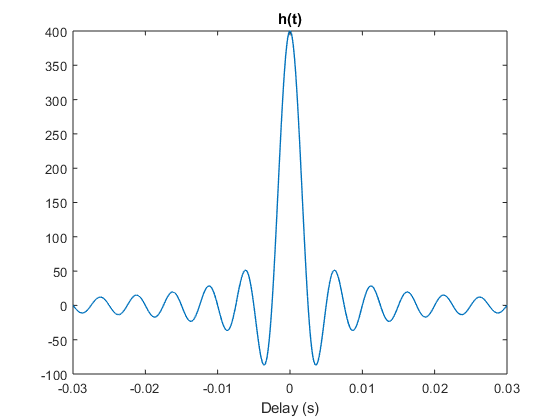

fc = 200; % Hz
wc = 2*pi*fc;
t = linspace(-0.03, 0.03, 5000); % implicit truncation of eternal function
h = (wc/pi)*sinc(wc*t/pi); % sinc arg gets divided by pi in MATLAB
figure
plot(t,h),title('h(t)'),xlabel('Delay (s)')

Turn this section on or off to optionally delay the (truncated) h(t) to make it causal.

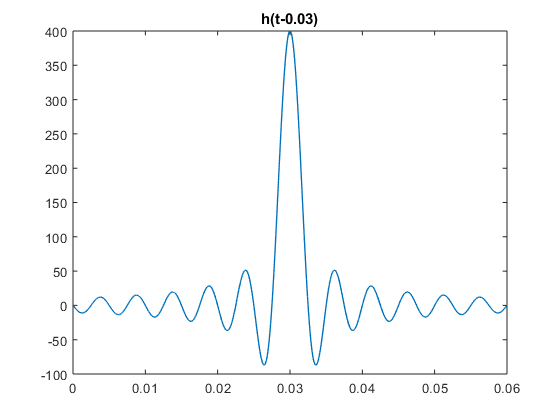

if true
    delay = -t(1); % also, try a small delay here and see how it affects phase plot
    t = t + delay;
    figure
    plot(t,h),title(sprintf('h(t-%g)',delay))
end

Calculate the corresponding H(omega) to make sure it matches. Note that the edges of the magnitude transition are not vertical and there are some oscillations due to truncating h(t). As discussed in class and per the time-delay property of the Fourier transform, the slope of the phase plot is the negative of the time delay.

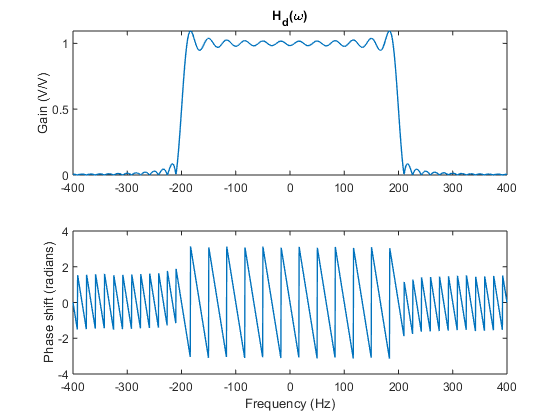

w = linspace(-2*wc,2*wc,1500);
dt = diff(t(1:2));
Hd = dt*sum(h' .* exp(-1j*t'*w), 1); % Approximate Fourier transform by Riemann sum
figure
subplot(211),plot(w/(2*pi),abs(Hd)),title('H_d(\omega)'),ylabel('Gain (V/V)')
subplot(212),plot(w/(2*pi),angle(Hd))
xlabel('Frequency (Hz)'),ylabel('Phase shift (radians)')

Now, modulate h(t). The modulation property of the Fourier transform tells us that this should result in a bandpass filter.

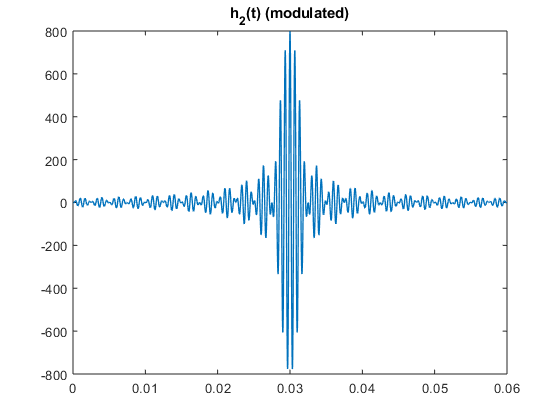

fm = 1500;
wm = fm*2*pi;
h2 = 2 * h .* cos(wm*t); % 2 compensates for 1/2 in modulation property
figure,plot(t,h2),title('h_2(t) (modulated)')

And, calculate the Fourier transform numerically and see if it matches expectations.

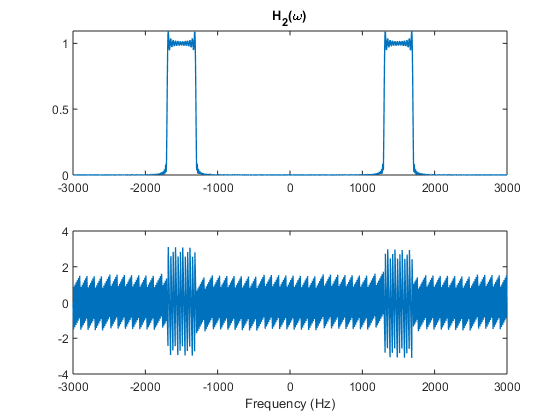

w = linspace(-2*wm,2*wm,1500);
H2 = dt*sum(h2' .* exp(-1j*t'*w), 1);
figure
subplot(211),plot(w/(2*pi),abs(H2)),title('H_2(\omega)')
subplot(212),plot(w/(2*pi),angle(H2)),xlabel('Frequency (Hz)')